clear; close all;
load Day_11_input.mat
puzzle_input(end:2048) = 0; % Preallocate (extend memory)
robot_painter = IntCode('puzzle_input', puzzle_input, 'instance_nr', 1, 'setting',0);
robot_painter.setup([0 0]);
grid_size = 100;
robot_position = [grid_size/2,grid_size/2]; %
robot_direction = [0,1]; %
robot_map = zeros(grid_size);
robot_painted_map = robot_map;
color_panel = 0;
n_painted_panels = 0;
i_robot = 0;
while not(robot_painter.done)
    % Starting panel
    color_panel = robot_map(robot_position(1),robot_position(2));
    prev_color_panel = color_panel; % Give it as input
    color_panel = robot_painter.step([color_panel color_panel]);
    direction = robot_painter.step([color_panel color_panel]);
    % Paint starting panel with whatever color robot says
    robot_painted_map(robot_position(1),robot_position(2))=1;
    robot_map(robot_position(1),robot_position(2)) = color_panel;
    if direction==0
        %fprintf("Turn left")
        robot_direction = turn_left(robot_direction);
    elseif direction==1
        %fprintf("Turn right")
        robot_direction = turn_right(robot_direction);
    end
    % Move robot
    robot_position = robot_position + robot_direction;
end
sum(sum(robot_painted_map)) % Solution

ans = 1565

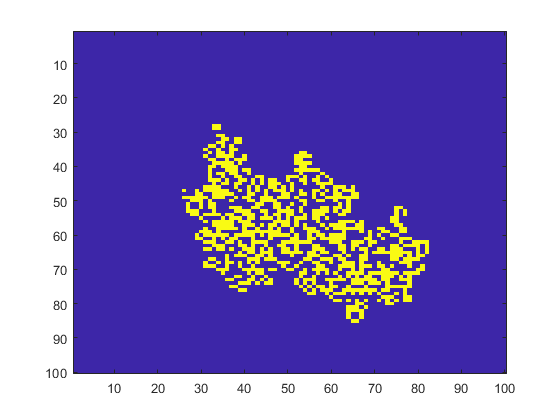

image(robot_map*255);

function direction = turn_right(direction)
tmp = direction(1);
direction(1) = direction(2);
direction(2) = -tmp;
end
function direction = turn_left(direction)
tmp = direction(1);
direction(1) = -direction(2);
direction(2) = tmp;
end
% Robot now moved, update map